Test randInt

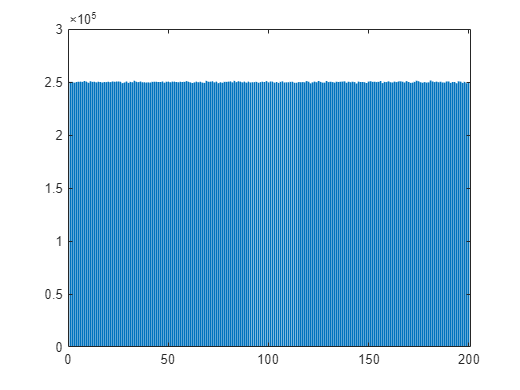

n_runs = 50000000;
maxi = 200;
results = zeros(1,n_runs);
counts = zeros(1,maxi);

for i=1:n_runs
    results(i) = randInt(maxi);
end

for i=1:maxi
    counts(i) = sum(results==i);
end

Px = (counts/n_runs);
Qx = (1/maxi);

bar(counts)

min_count = min(counts)

min_count = 248541

max_count = max(counts)

max_count = 251438

expected = n_runs/maxi

expected = 250000

divergence = sum(Px.*log(Px/Qx)) % Kullback–Leibler (KL) divergence

divergence = 2.1015e-06